### Лабораторная работа №9

#### Реализовать метод матричного переноса на слоистой гетероструктуре.

clc; clear;

hbar = 1.054e-34;
m = 9.109e-31;

Пока всё легко.

% Number of abstract materials we have
% And their random properties
numberOfMaterials = 5;  % Editable <---------
meff = m * rand(1, numberOfMaterials);
fullEnergy = 2e-19;     % Editable <---------
UPotential = sqrt(rand(1, numberOfMaterials)) * fullEnergy;   

Задаём количество слоёв в гетероструктуре и полную энергию.

Т.к. данных нет, в голове представляем, что потенциальная энергия и эффективная масса совсем не случайные значения.

% Sum of the length of past layers and the current one in fractions.
layersLength = sort( rand(1, numberOfMaterials) );
layersLength(end) = 1;

Итак. Здесь имеем разные барьеры на разных координатах (высотах). Координаты рандомим, рандом сортируем и вуа-ля!

Получаем доли от 1, где 1 - конец гетероструктуры.

Далее просто понимаем по соотношению координаты к толщине структуры к каком из барьеров мы сейчас находимся.

% I have no idea how to declare constants in MatLab,
% so just used upper case.
% 1000 is enough.
N_OF_POINTS = 1000;     % Editable <----------

% Thickness of the heterostructure.
structureThickness = 30e-9;     % Editable <----------

Еще парочка величин, которые можно варьировать. Здесь количество точек для численного метода и толщина структуры.

% Primitive flat map where keys (first row of the array)
% are identifiers of abstract materials.
% Values are x coordinate.
materialKeyXValuePair = zeros(2, N_OF_POINTS);
materialKeyXValuePair(2, :) = linspace(0, structureThickness, N_OF_POINTS);

Создаём аналог плоской мапы (словаря и пр.).

% Making keys
temporaryCount = 1;
for n = 1 : N_OF_POINTS
    if (materialKeyXValuePair(2, n) / structureThickness) > ...
            layersLength(temporaryCount)
        temporaryCount = temporaryCount + 1;
    end
    materialKeyXValuePair(1, n) = temporaryCount;
end

Собственно по долям потенц. барьеров мы можем определить, где +- по координате они заканчиваются.

В карте по сути то нет значений. Скорее пара ключ-ключ. Где первая строка - номер условного материала (а в соответсвии стоит потенциальная энергия и эффективная масса), а вторая строка - координата.

% Calculating gamma for each point
gammaCoefficient = zeros(1, N_OF_POINTS);
for n = 1 : N_OF_POINTS
    gammaCoefficient(n) = sqrt( 2 * meff(materialKeyXValuePair(1, n)) * ...
        (fullEnergy - UPotential(materialKeyXValuePair(1, n)) ) ) / hbar;
end 

Просто посчитали коэффициент гамма с учетом того, что на последовательных координатах меняется эффективная масса электрона.

% Matrix of An, Bn coefficients.
% 1st row - A, 2nd row - B.
ABCoefficients = zeros(2, N_OF_POINTS);
ABCoefficients(2, 1) = rand() + 1i * rand();     % Editable <----------
tempK = (rand() - 1) * 2;
ABCoefficients(1, 1) = tempK + 1i * sqrt(1 - tempK ^ 2);     % Should it workes correctly?     % Editable <----------

Наши будущие коэффициенты. B0 - случайно, а A0 так, чтобы квадрат модуля был равен единице.

Напоминаю, первая строка - коэффициенты А.

% Most awful thing. T - matrix of matrix of matrix.
% Some of point are equal to identity matrix.
% Reason is potential energy in x point equals potential energy in x + 1
% point.
% It's ok because of identity matrix product does not affect the final
% result.
T = zeros(2, 2, N_OF_POINTS);
for n = 2 : N_OF_POINTS     % starts with 2nd index
    T(:, :, n) = reshape([0.5 * (1 + (gammaCoefficient(n - 1) * meff( materialKeyXValuePair(1, n) ) ...
        / gammaCoefficient(n) / meff(materialKeyXValuePair(1, n - 1)) )) * ...
        exp( -1i * (gammaCoefficient(n) - gammaCoefficient(n - 1)) ...
        * materialKeyXValuePair(2, n) ) 
        
        0.5 * (1 - (gammaCoefficient(n - 1) * meff( materialKeyXValuePair(1, n) ) ...
        / gammaCoefficient(n) / meff(materialKeyXValuePair(1, n - 1)) )) * ...
        exp( -1i * (gammaCoefficient(n) + gammaCoefficient(n - 1)) ...
        * materialKeyXValuePair(2, n) ) 
        
        0.5 * (1 - (gammaCoefficient(n - 1) * meff( materialKeyXValuePair(1, n) ) ...
        / gammaCoefficient(n) / meff(materialKeyXValuePair(1, n - 1)) )) * ...
        exp( 1i * (gammaCoefficient(n) + gammaCoefficient(n - 1)) ...
        * materialKeyXValuePair(2, n) )  
        
        0.5 * (1 + (gammaCoefficient(n - 1) * meff( materialKeyXValuePair(1, n) ) ...
        / gammaCoefficient(n) / meff(materialKeyXValuePair(1, n - 1)) )) * ...
        exp( 1i * (gammaCoefficient(n) - gammaCoefficient(n - 1)) ...
        * materialKeyXValuePair(2, n) ) 
        ], 2, 2);
end

Выглядит страшно, если что-то здесь поломается, то еще страшнее.

По сути, мы здесь задаем для каждой координаты матрицу Т.

Почему для каждой координаты, а не только для переходов?

Во-первых. Надо думать. Так проще.

Во-вторых, мы можем это сделать, т.к. на одном потенциальном уровне значения Т для рядом стоящих координат и коэффициентов А и В будут равны единичной матрице, а, следовательно, находя следующую пару коэффициентов на шаге внутри одного потенциального уровня, коэффициенты меняться не будут, что вполне приятно.

Все эти дикие формулы на самом деле очень короткие. Просто имена переменных длинные.

Ну и здесь фокус с эффективной массой. Значений в массиве meff на каждый материал (у меня 5). А вот Т у нас много (тыща).

Поэтому выкручиваемся и берём для meff индекс из первой строчки таблицы соответствия координаты к материалу (materialKeyXValuePair)

% Finally calculating coefficients A n B.
for n = 2 : N_OF_POINTS
    ABCoefficients(:, n) = T(:, :, n) * ABCoefficients(:, n - 1);
end

Просчитываем коэффициенты, имея начальные.

Просчитываем для каждой точки.

% Time to make values of psi-function without for-cycles.
psiValues = ABCoefficients(1, :) .* exp( 1i .* gammaCoefficient .* materialKeyXValuePair(2, :)) + ...
    ABCoefficients(2, :) .* exp( - 1i .* gammaCoefficient .* materialKeyXValuePair(2, :));

И считаем значения пси функции. Даже без цикла (потому что не надо брать предыдущий шаг).

%??? Normalize ???
psiValues = psiValues * structureThickness / N_OF_POINTS;

Далее делаем это по приколу.

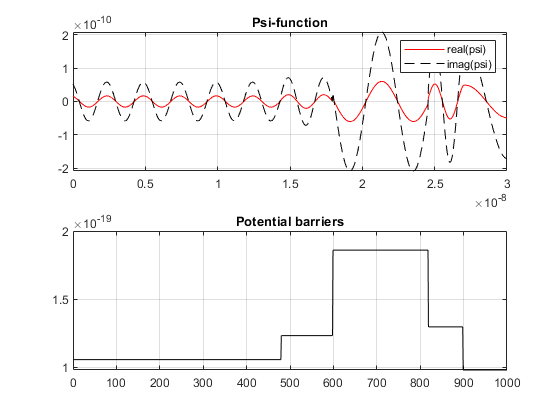

figure;

subplot(2, 1, 1);
plot(materialKeyXValuePair(2, :), real(psiValues), 'r'); hold on;
plot(materialKeyXValuePair(2, :), imag(psiValues), 'k--'); grid on; hold off;
legend('real(psi)', 'imag(psi)');
title('Psi-function');

subplot(2, 1, 2);
plot(UPotential(materialKeyXValuePair(1, :)), 'k'); grid on;
title('Potential barriers');

И строим волну сверху. Профиль снизу для понимания происходящего.

Не забываем пару раз поиграться, чтобы рандомайзер выдал что-то +- приличное.

#### Вывод: просчитали значения пси функции методом переноса матриц для подобия слоистой гетероструктуры.